# 1.

## a)


$$\begin{array}{l}
\dot{\;x_1 } =4\left(x_2 -x_1 \right)+2\left(x_4 -x_1 \right)=4x_2 -6x_1 +2x_4 \\
\dot{\;x_2 } =2\left(x_1 -x_2 \right)-2\left(x_4 -x_2 \right)=2x_1 -2x_4 \\
\dot{\;x_3 } =x_3 +\left(x_1 -x_3 \right)+x_5 -x_{3\;} =x_{1\;} +x_5 -x_3 \\
\dot{\;x_4 } =4\left(x_2 -x_4 \right)-4\left(x_1 -x_4 \right)\;=4x_2 -4x_1 \\
\dot{\;x_5 } =6\left(x_1 -x_5 \right)+x_3 -x_5 =6x_1 +x_3 -7x_5 
\end{array}$$


## b)

A = [-6 4 0 2 0; 2 0 0 -2 0; 1 0 -1 0 1; -4 4 0 0 0; 6 0 1 0 -7]

A =     -6     4     0     2     0
     2     0     0    -2     0
     1     0    -1     0     1
    -4     4     0     0     0
     6     0     1     0    -7


## c)

[la, Va] = eig(A)

la =    -0.0000   -0.4189    0.3795   -0.3323   -0.0000
   -0.0000   -0.0000    0.1265   -0.3323   -0.0000
    0.1602    0.3770   -0.6957   -0.7200    0.9871
   -0.0000   -0.4189    0.5060   -0.3323   -0.0000
   -0.9871   -0.7121    0.3162   -0.3877    0.1602


Va =    -7.1623         0         0         0         0
         0   -4.0000         0         0         0
         0         0   -2.0000         0         0
         0         0         0   -0.0000         0
         0         0         0         0   -0.8377


Todos los autovalores son distintos. De la ec. 3.18 del manual, se observa que el autovector que no evoluciona a 0 es la cuarta columna. De esta manera, se concluye. 

- Los señores 1, 2 y 4 terminan con la misma opinión

- El señor 3 es el menos indiferente

- Todos los señores terminan con el mismo signo, el cual será opuesto a la constante ci que determinen las condiciones iniciales.

## d)

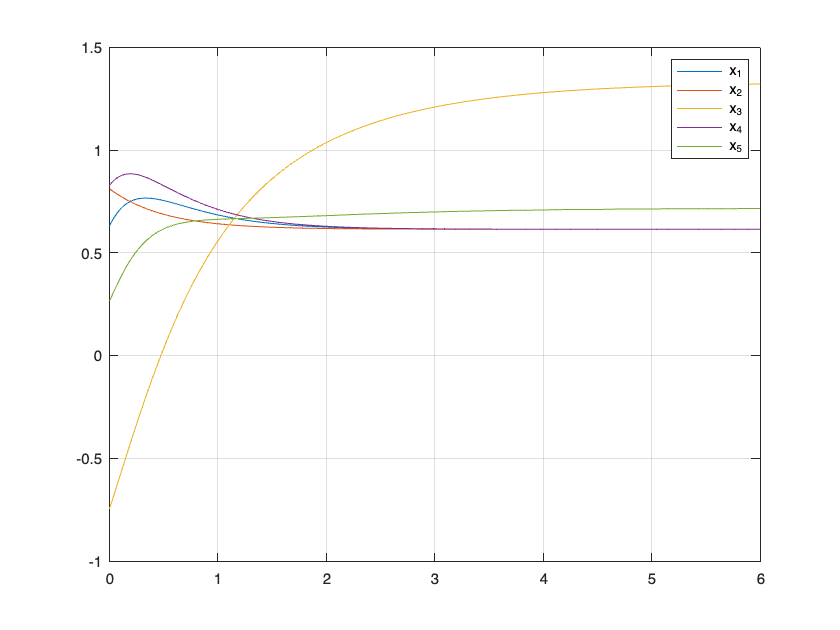

x0 = [];
for i = 1:5
    x0(i) = -1 + 2*rand(1);
end

[t, x] = ode45(@(t, x)A*x, [0 6], x0');

figure(1);
plot(t, x); grid on;
legend("x_1", "x_2", "x_3", "x_4", "x_5");

## e)

Estudiar los autovectores de A traspuesta.

[lat, Vat] = eig(A')

lat =    -0.8018   -0.7071    0.5774    0.6256   -0.8512
    0.2673    0.0000    0.5774    0.3343    0.2964
         0         0         0   -0.1122   -0.0467
    0.5345    0.7071   -0.5774   -0.6956    0.3205
         0         0         0   -0.0182    0.2875


Vat =    -4.0000         0         0         0         0
         0   -2.0000         0         0         0
         0         0    0.0000         0         0
         0         0         0   -0.8377         0
         0         0         0         0   -7.1623


La forma de B será una matriz columna de tres ceros y dos unos. Por tanto, se puede ver inmediatamente que actuando sobre las personas tres y cinco hay tres autovectores en el kernel de B', por lo que no será controlable. También se puede ver que si se actúa en 2 y en 5 o en 2 y en 3, hay un autovector en el kernel de B'. Algo similar pasa con 1 y 4 (2 vectores en el kernel de B'). Actuando en 4 y 5 no debería hacber ningún problema.

B1 = [0 0 1 0 1]';
B2 = [0 1 1 0 0]';
B3 = [1 0 0 1 0]';
B = [0 0 0 1 1]';

r1 = rank(ctrb(A, B1)) %Debería salir 2

r1 = 2

r2 = rank(ctrb(A, B2)) %Debería salir 4

r2 = 4

r3 = rank(ctrb(A, B3)) %Debería salir 3

r3 = 3

r = rank(ctrb(A, B)) %Debería salir 5, es decir, actuando en P4 y P5 el sistema es controlable

r = 5

 Elijo entonces a las personas 4 y 5. Otras opciones son la 1 y la 2 o la 1 y la 5. 

## f)

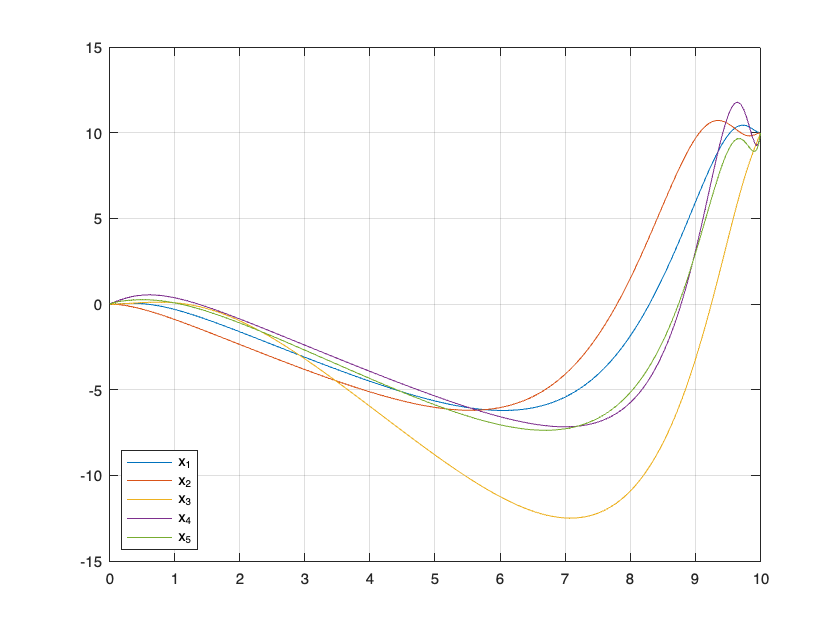

%Como hemos elegido influir a las personas 4 y 5 y queremos que al final
%todos piensen 10,
C = [0 0 0 1 1];
x1 = repelem(10, 5)';
%Pero además queremos que llegue en 10 días.
Wr = integral(@(t) dgram(t, 10, A, B), 0, 10, "ArrayValued", 1);
eta1 = Wr\x1;
%Y ya podemos construir el sistema de la forma xdot = A * x + B * u con u =
%B' * expm(A *(10 - t) * eta1

[t, x] = ode45(@(t, x) A * x + B * B' * expm(A' * (10 - t)) * eta1, [0 10], [0 0 0 0 0]');
figure(2)
plot(t, x); grid on;
legend("x_1", "x_2", "x_3", "x_4", "x_5", "Location", "southwest");

## g)

Para saber a cuántos hay que entrevistar, necesitamos conocer la observabilidad del sistema. Conviene recordar los autovectores de A

la %WHY ON EARTH DID I NAME 'EM THIS WAY

la =    -0.0000   -0.4189    0.3795   -0.3323   -0.0000
   -0.0000   -0.0000    0.1265   -0.3323   -0.0000
    0.1602    0.3770   -0.6957   -0.7200    0.9871
   -0.0000   -0.4189    0.5060   -0.3323   -0.0000
   -0.9871   -0.7121    0.3162   -0.3877    0.1602


Podemos ver inmediatamente que solo hace falta estudiar al individuo 3 o al 5 para tener plena observabilidad del sistema. Si observamos al 1, hay 2 autovectores en el kernel de C. Si observamos al 2, hay 3. Con el 4 hay otros 2.

%Comprobamos estudiando la matriz de observabilidad
C3 = [0 0 1 0 0];
C5 = [0 0 0 0 1];
o3 = rank(obsv(A, C3)) %Debería ser 5.

o3 = 5

o5 = rank(obsv(A, C5)) %Igual.

o5 = 5

Ahora vamos a construir un sistema con un estimador. Para ello vamos a usar la observabilidad de la persona 3. El sistema con el estimador es

%Construimos el estimador (ec. 4.56) -> solo se va a tomar una señal de
%estimador que es la y del 3. 
L = place(A', C3', [-3.5 -4 -5 -6 -7])' %Queremos que el estimador converja al sistema, luego todos los polos serán negativos

L =    24.1783
   26.9056
   11.5000
   22.8147
   20.3217


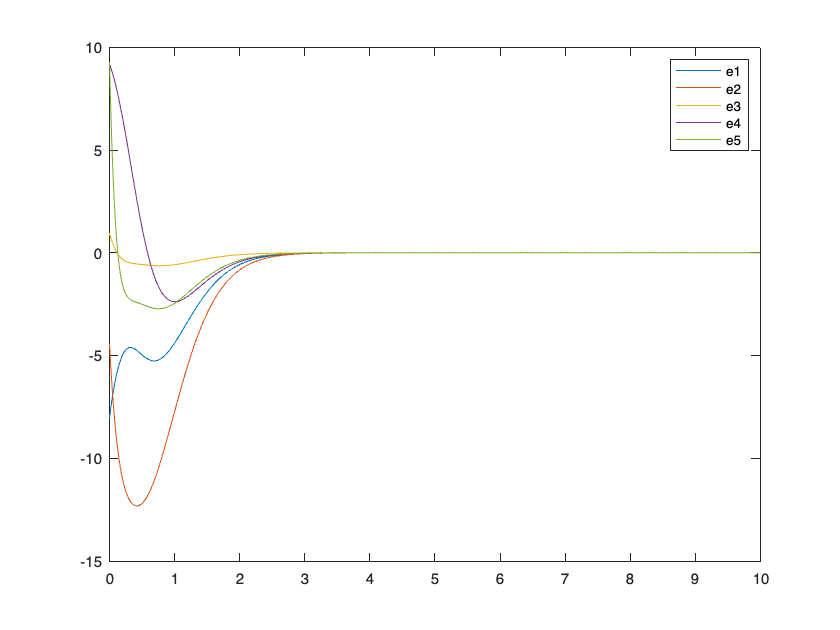

%y = C3 * x
%yhat = C3 * xhat 
%Mismo gramiano, mismas condiciones. Esto tiene que converger al sistema,
%i.e. los errores yhat - y van a 0.
[t, z] = ode45(@(t, z) estimador(t, z, A, B, C3, L, eta1), [0 10], [0; 0; 0; 0; 0; -10 + 20 * rand(5,1)]);
figure(3)
plot(t, z(:,6:10) - z(:, 1:5))
legend("e1", "e2", "e3", "e4", "e5");

Se ve que todos los errores van a 0 bastante antes de 10.

## h)

Pone de hacer LQR pero voy a resolverlo utilizando control por realimentación de estados estimados sin más.

%La ganancia será calculada como siempre
K = place(A, B, [-1 -1.5 -2 -2.5 -3])

K =     5.7477   -2.6219    0.3591   -1.7641   -2.2359


Aamp = [A, -B*K; L*C3, A-B*K-L*C3]

Aamp =    -6.0000    4.0000         0    2.0000         0         0         0         0         0         0
    2.0000         0         0   -2.0000         0         0         0         0         0         0
    1.0000         0   -1.0000         0    1.0000         0         0         0         0         0
   -4.0000    4.0000         0         0         0   -5.7477    2.6219   -0.3591    1.7641    2.2359
    6.0000         0    1.0000         0   -7.0000   -5.7477    2.6219   -0.3591    1.7641    2.2359
         0         0   24.1783         0         0   -6.0000    4.0000  -24.1783    2.0000         0
         0         0   26.9056         0         0    2.0000         0  -26.9056   -2.0000         0
         0         0   11.5000         0         0    1.0000         0  -12.5000         0    1.0000
         0         0   22.8147         0         0   -9.7477    6.6219  -23.1738    1.7641    2.2359
         0         0   20.3217         0         0    0.2523    2.6219  -19.6808    

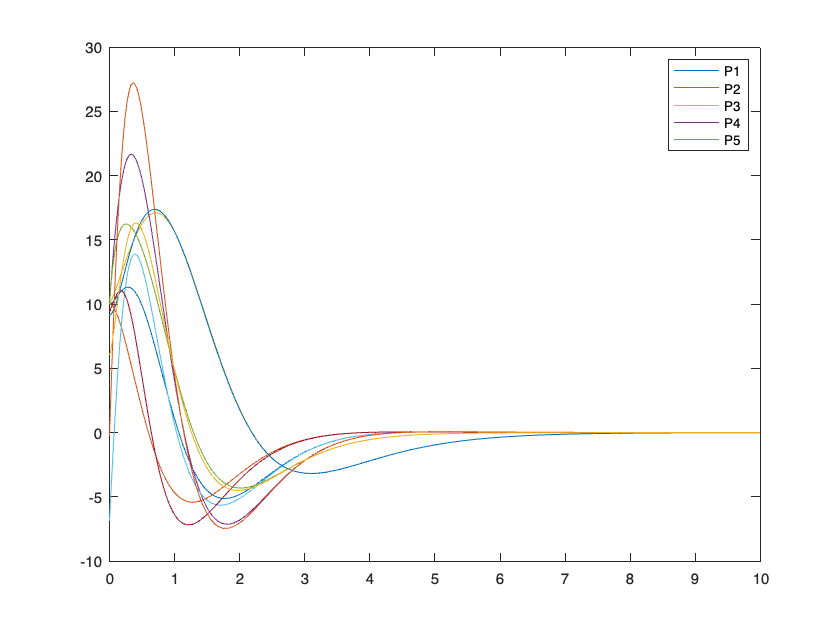

[t, xamp] = ode45(@(t, x) Aamp * x, [0 10], [x1; -10 + 20 * rand(5,1)]); %El estimador empieza en sitio random y estados en 10.

figure(4)
plot(t, xamp)
legend("P1", "P2", "P3", "P4", "P5");

function dwr = dgram(t, t1, A, B)
    dwr = expm(A*(t1 - t)) * (B * B') * expm(A'*(t1 - t));
end

function zdot = estimador(t, z, A, B, C, L, eta)
    zdot(1:5,1) = A * z(1:5,1) + B * B' * expm(A' * (10 - t)) * eta;
    zdot(6:10,1) = A * z(6:10,1) + B * B' * expm(A' * (10 - t)) * eta - L * C * (z(6:10,1) - z(1:5,1)); %Los cinco primeros valores de z son x y los últimos 5 los del estimador
end